# Tutorial 5 - Simulate CC-CV Cycling

## Introduction

In this tutorial, we will use a P2D model to simulate CC-CV cycling. After completing this tutorial, you should have a working knowledge of:

- How to define and modify cycling protocols in BattMo

We'll use the same model from Tutorial 1.

jsonstruct = parseBattmoJson('Examples/jsondatafiles/sample_input.json');

Parameters are defined in the JSON parameter file and parsed into the MATLAB structure. Once the JSON file has been read into MATLAB as a jsonstruct, its properties can be modified programmatically.

## Explore the Control Definition

Let's begin by reviewing the control protocol in BattMo, with the command:

disp(jsonstruct.Control)

         controlPolicy: 'CCDischarge'
                 DRate: 1
    lowerCutoffVoltage: 3
    upperCutoffVoltage: 4.1000
             dIdtLimit: 0.0100
             dEdtLimit: 0.0100
            rampupTime: 0.1000



We see that the default control protocol is set to a constant current (galvanostatic) discharge. To change to a CC-CV cycling protocol, we can use the command:

cccv_control_protocol = parseBattmoJson('cccv_control.json');
jsonstruct_modified = mergeStructs({cccv_control_protocol, jsonstruct});

mergeStructs: Parameter Control.controlPolicy is assigned twice with different values. Value from first jsonstruct is used.
mergeStructs: Parameter Control.lowerCutoffVoltage is assigned twice with different values 2.8 and 3, relative difference is 0.0344828. Value from first jsonstruct is used.
mergeStructs: Parameter Control.upperCutoffVoltage is assigned twice with different values 4.2 and 4.1, relative difference is 0.0120482. Value from first jsonstruct is used.
mergeStructs: Parameter Control.dIdtLimit is assigned twice with different values 2e-06 and 0.01, relative difference is 0.9996. Value from first jsonstruct is used.
mergeStructs: Parameter Control.dEdtLimit is assigned twice with different values 2e-06 and 0.01, relative difference is 0.9996. Value from first jsonstruct is used.


Now we can explore the modified control protocol definition with the command:

disp(jsonstruct_modified.Control)

         controlPolicy: 'CCCV'
        initialControl: 'discharging'
        numberOfCycles: 5
                 CRate: 0.5000
                 DRate: 1
    lowerCutoffVoltage: 2.8000
    upperCutoffVoltage: 4.2000
             dIdtLimit: 2.0000e-06
             dEdtLimit: 2.0000e-06
            rampupTime: 0.1000



Let's run the simulation and plot the cell voltage curve.

% run the simulation
output = runBattery(jsonstruct_modified);

Solving timestep 001/135:          -> 15 Seconds, 625 Milliseconds
Solving timestep 002/135: 15 Seconds, 625 Milliseconds -> 31 Seconds, 250 Milliseconds
Solving timestep 003/135: 31 Seconds, 250 Milliseconds -> 62 Seconds, 500 Milliseconds
Solving timestep 004/135: 62 Seconds, 500 Milliseconds -> 125 Seconds
Solving timestep 005/135: 125 Seconds -> 250 Seconds
Solving timestep 006/135: 250 Seconds -> 500 Seconds
Solving timestep 007/135: 500 Seconds -> 1000 Seconds
Solving timestep 008/135: 1000 Seconds -> 1500 Seconds
Solving timestep 009/135: 1500 Seconds -> 2000 Seconds
Solving timestep 010/135: 2000 Seconds -> 2500 Seconds
Solving timestep 011/135: 2500 Seconds -> 3000 Seconds
Solving timestep 012/135: 3000 Seconds -> 3500 Seconds
Solving timestep 013/135: 3500 Seconds -> 1 Hour, 400 Seconds
Solving timestep 014/135: 1 Hour, 400 Seconds -> 1 Hour, 900 Seconds
Solving timestep 015/135: 1 Hour, 900 Seconds -> 1 Hour, 1400 Seconds
Solving timestep 016/135: 1 Hour, 1400 Seconds -> 1 H

Solver failure after 3 iterations for timestep of length 500 Seconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 250 Seconds. Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 125 Seconds. Cutting timestep.
Solving timestep 017/135: 1 Hour, 1900 Seconds -> 1 Hour, 2400 Seconds
Solving timestep 018/135: 1 Hour, 2400 Seconds -> 1 Hour, 2900 Seconds
Solving timestep 019/135: 1 Hour, 2900 Seconds -> 1 Hour, 3400 Seconds
Solving timestep 020/135: 1 Hour, 3400 Seconds -> 2 Hours, 300 Seconds
Solving timestep 021/135: 2 Hours, 300 Seconds -> 2 Hours, 800 Seconds
Solving timestep 022/135: 2 Hours, 800 Seconds -> 2 Hours, 1300 Seconds
Solving timestep 023/135: 2 Hours, 1300 Seconds -> 2 Hours, 1800 Seconds
Solving timestep 024/135: 2 Hours, 1800 Seconds -> 2 Hours, 2300 Seconds
Solving timestep 025/135: 2 Hours, 2300 Seconds -> 2 Hours, 2800 Seconds
So

Solver failure after 3 iterations for timestep of length 500 Seconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 250 Seconds. Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 125 Seconds. Cutting timestep.
Solving timestep 043/135: 5 Hours, 500 Seconds -> 5 Hours, 1000 Seconds
Solving timestep 044/135: 5 Hours, 1000 Seconds -> 5 Hours, 1500 Seconds
Solving timestep 045/135: 5 Hours, 1500 Seconds -> 5 Hours, 2000 Seconds
Solving timestep 046/135: 5 Hours, 2000 Seconds -> 5 Hours, 2500 Seconds
Solving timestep 047/135: 5 Hours, 2500 Seconds -> 5 Hours, 3000 Seconds
Solving timestep 048/135: 5 Hours, 3000 Seconds -> 5 Hours, 3500 Seconds
Solving timestep 049/135: 5 Hours, 3500 Seconds -> 6 Hours, 400 Seconds
Solving timestep 050/135: 6 Hours, 400 Seconds -> 6 Hours, 900 Seconds
Solving timestep 051/135: 6 Hours, 900 Seconds -> 6 Hours, 1400 Seco

Solver failure after 3 iterations for timestep of length 500 Seconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 250 Seconds. Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 125 Seconds. Cutting timestep.
Solving timestep 068/135: 8 Hours, 2200 Seconds -> 8 Hours, 2700 Seconds
Solving timestep 069/135: 8 Hours, 2700 Seconds -> 8 Hours, 3200 Seconds
Solving timestep 070/135: 8 Hours, 3200 Seconds -> 9 Hours, 100 Seconds
Solving timestep 071/135: 9 Hours, 100 Seconds -> 9 Hours, 600 Seconds
Solving timestep 072/135: 9 Hours, 600 Seconds -> 9 Hours, 1100 Seconds
Solving timestep 073/135: 9 Hours, 1100 Seconds -> 9 Hours, 1600 Seconds
Solving timestep 074/135: 9 Hours, 1600 Seconds -> 9 Hours, 2100 Seconds
Solving timestep 075/135: 9 Hours, 2100 Seconds -> 9 Hours, 2600 Seconds
Solving timestep 076/135: 9 Hours, 2600 Seconds -> 9 Hours, 3100 Sec

Solver failure after 3 iterations for timestep of length 500 Seconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 250 Seconds. Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 125 Seconds. Cutting timestep.
Solving timestep 094/135: 12 Hours, 800 Seconds -> 12 Hours, 1300 Seconds
Solving timestep 095/135: 12 Hours, 1300 Seconds -> 12 Hours, 1800 Seconds
Solving timestep 096/135: 12 Hours, 1800 Seconds -> 12 Hours, 2300 Seconds
Solving timestep 097/135: 12 Hours, 2300 Seconds -> 12 Hours, 2800 Seconds
Solving timestep 098/135: 12 Hours, 2800 Seconds -> 12 Hours, 3300 Seconds
Solving timestep 099/135: 12 Hours, 3300 Seconds -> 13 Hours, 200 Seconds
Solving timestep 100/135: 13 Hours, 200 Seconds -> 13 Hours, 700 Seconds
Solving timestep 101/135: 13 Hours, 700 Seconds -> 13 Hours, 1200 Seconds
Solving timestep 102/135: 13 Hours, 1200 Seconds -> 1

Solver failure after 3 iterations for timestep of length 500 Seconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 250 Seconds. Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 125 Seconds. Cutting timestep.
Solving timestep 120/135: 15 Hours, 3000 Seconds -> 15 Hours, 3500 Seconds
Solving timestep 121/135: 15 Hours, 3500 Seconds -> 16 Hours, 400 Seconds
Solving timestep 122/135: 16 Hours, 400 Seconds -> 16 Hours, 900 Seconds
Solving timestep 123/135: 16 Hours, 900 Seconds -> 16 Hours, 1400 Seconds
Solving timestep 124/135: 16 Hours, 1400 Seconds -> 16 Hours, 1900 Seconds
Solving timestep 125/135: 16 Hours, 1900 Seconds -> 16 Hours, 2400 Seconds
Solving timestep 126/135: 16 Hours, 2400 Seconds -> 16 Hours, 2900 Seconds
Solving timestep 127/135: 16 Hours, 2900 Seconds -> 16 Hours, 3400 Seconds
Solving timestep 128/135: 16 Hours, 3400 Seconds -> 

get the states

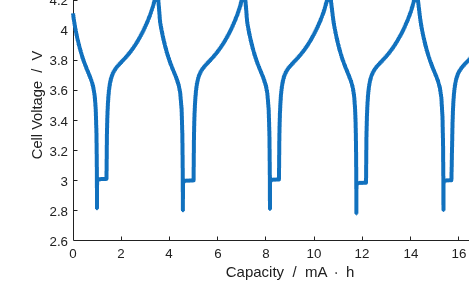

states = output.states;

% extract the time and voltage quantities
time = cellfun(@(state) state.time, states);
voltage = cellfun(@(state) state.('Control').E, states);
current = cellfun(@(state) state.('Control').I, states);

% calculate the capacity
capacity = time .* current;

% plot the discharge curve in the figure
plot(time/hour, voltage, '-', 'linewidth', 3)

% add plot annotations
xlabel('Capacity  /  mA \cdot h')
ylabel('Cell Voltage  /  V')

## Summary

In this tutorial, we explored how to modify material parameters in BattMo.